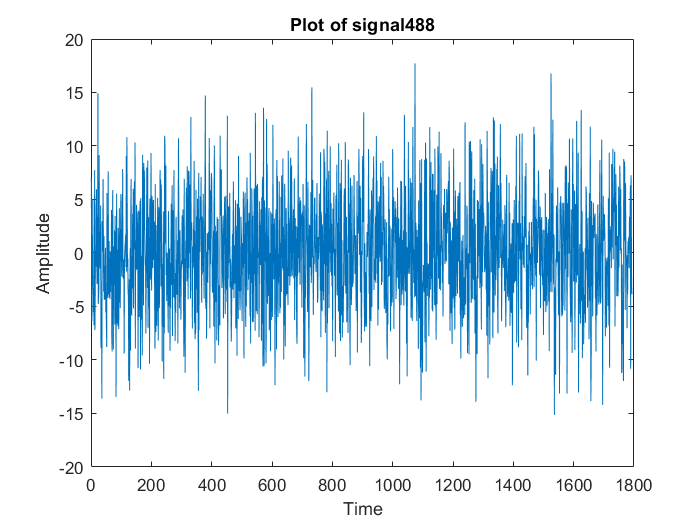

% Load the mat file
load('signal488.mat', 'xn_test');

% Plot the signal
plot(xn_test);

% Add labels and title for clarity
xlabel('Time');
ylabel('Amplitude');
title('Plot of signal488');

% Construct subsets
S1 = xn_test(1:128);
S2 = xn_test(1:256);
S3 = xn_test(1:512);
S4 = xn_test(1:1024);
S5 = xn_test(1:1792);

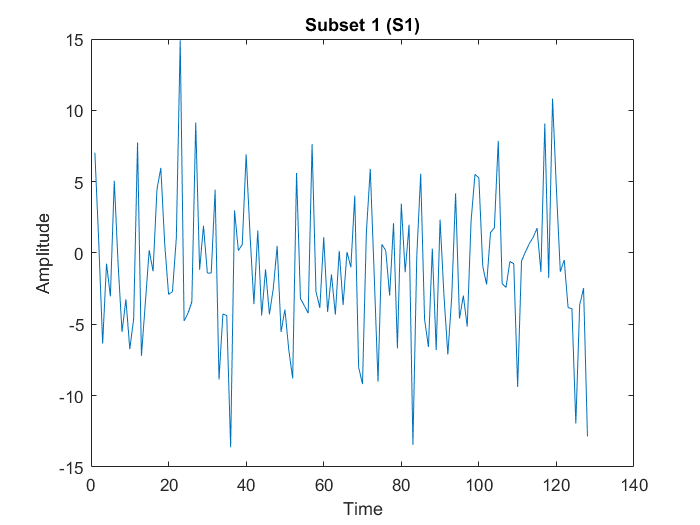

% Plot constructed subsets
plot(S1);
xlabel('Time');
ylabel('Amplitude');
title('Subset 1 (S1)');

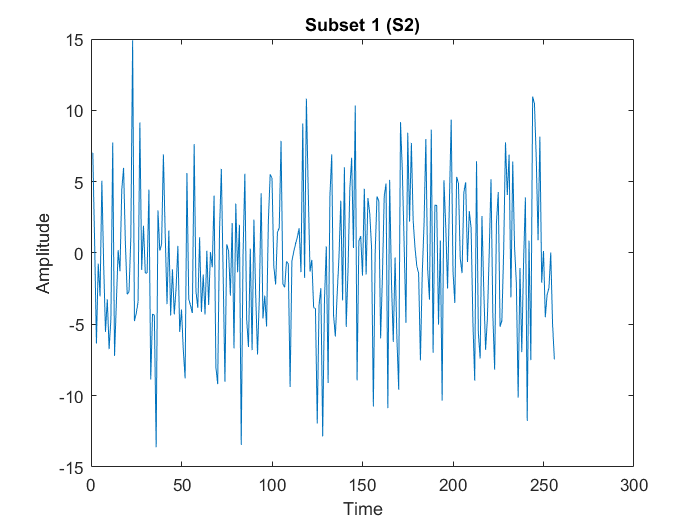


plot(S2);
xlabel('Time');
ylabel('Amplitude');
title('Subset 1 (S2)');

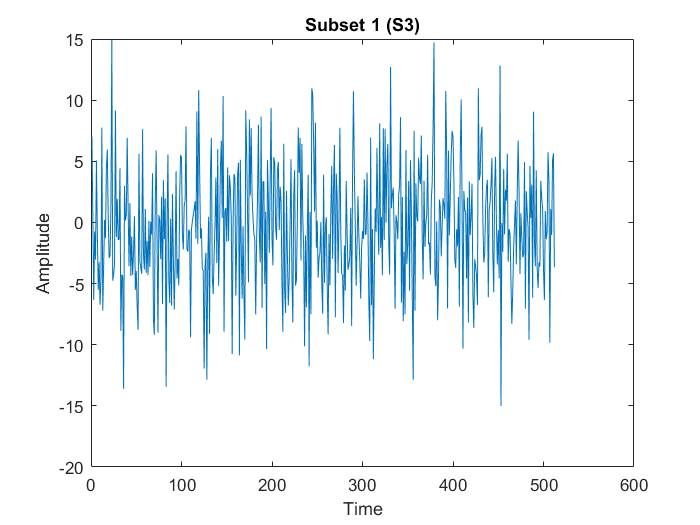


plot(S3);
xlabel('Time');
ylabel('Amplitude');
title('Subset 1 (S3)');

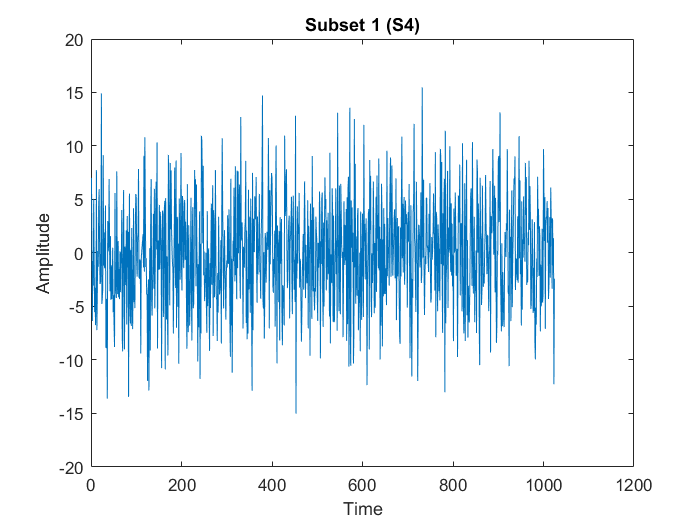


plot(S4);
xlabel('Time');
ylabel('Amplitude');
title('Subset 1 (S4)');

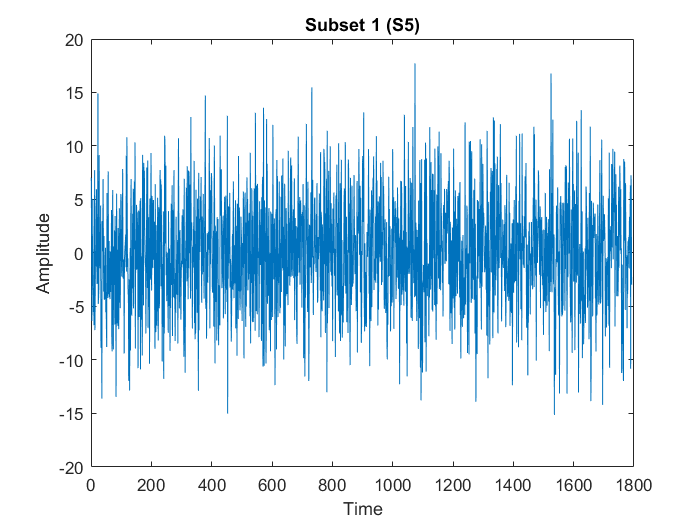


plot(S5);
xlabel('Time');
ylabel('Amplitude');
title('Subset 1 (S5)');

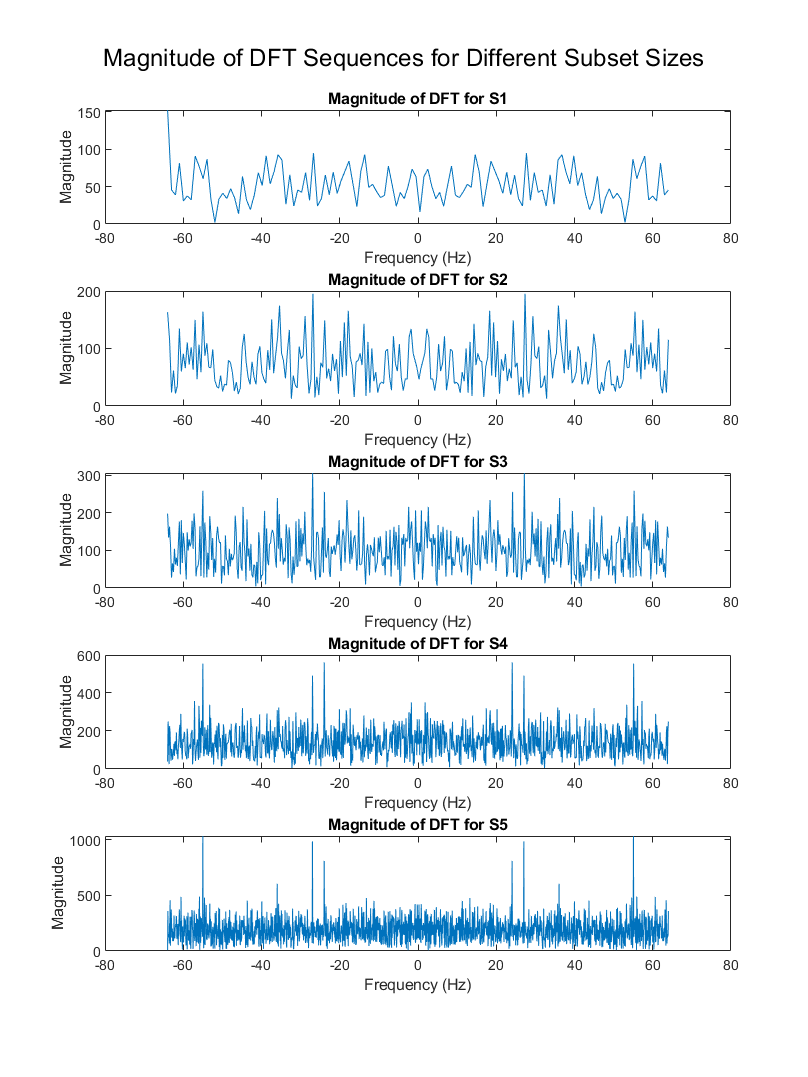

% Define the sampling rate (fs) and the length of the DFT
fs = 128; % Sampling rate in Hz

% Length of each subset
N1 = length(S1);
N2 = length(S2);
N3 = length(S3);
N4 = length(S4);
N5 = length(S5);

% Compute the DFT for each subset
DFT_S1 = fft(S1, N1);
DFT_S2 = fft(S2, N2);
DFT_S3 = fft(S3, N3);
DFT_S4 = fft(S4, N4);
DFT_S5 = fft(S5, N5);

% Compute the frequency axes for plotting
frequencies1 = linspace(-fs/2, fs/2, N1);
frequencies2 = linspace(-fs/2, fs/2, N2);
frequencies3 = linspace(-fs/2, fs/2, N3);
frequencies4 = linspace(-fs/2, fs/2, N4);
frequencies5 = linspace(-fs/2, fs/2, N5);

% Plot the magnitude of the DFT sequences
figure('Position', [100, 100, 1500, 2000]);

subplot(5, 1, 1);
plot(frequencies1, abs(DFT_S1));
title('Magnitude of DFT for S1');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

subplot(5, 1, 2);
plot(frequencies2, abs(DFT_S2));
title('Magnitude of DFT for S2');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

subplot(5, 1, 3);
plot(frequencies3, abs(DFT_S3));
title('Magnitude of DFT for S3');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

subplot(5, 1, 4);
plot(frequencies4, abs(DFT_S4));
title('Magnitude of DFT for S4');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

subplot(5, 1, 5);
plot(frequencies5, abs(DFT_S5));
title('Magnitude of DFT for S5');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

% Adjust the plot layout for better visualization
sgtitle('Magnitude of DFT Sequences for Different Subset Sizes');


% Display the plot

% Define the parameters
K = 128;  % Number of samples in each subset
L = 14;   % Number of subsets
N = L * K; % Total number of samples

% Initialize a cell array to store the subsets
subsets = cell(1, L);

% Partition the input signal into L subsets
for i = 1:L
    start_idx = (i - 1) * K + 1;
    end_idx = i * K;
    subsets{i} = xn_test(start_idx:end_idx);
end

% Each subset is stored in the 'subsets' cell array, e.g., subsets{1} contains the first subset, subsets{2} contains the second subset, and so on.

% Apply dft for each subset

% Initialize a cell array to store the dft of subsets
dft_subsets = cell(1, L);

for i = 1:L
    dft_subsets{i} = fft(subsets{i},K);
end

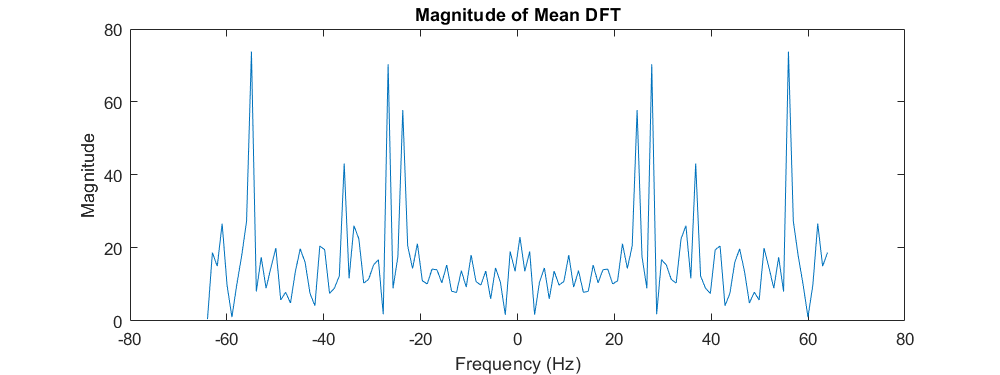

% Calculate the arithmetic mean of the L sets of DFT sequences
mean_DFT = zeros(1, K);  % Initialize an array to store the mean DFT

for i = 1:L
    mean_DFT = mean_DFT + dft_subsets{i};
end

mean_DFT = mean_DFT / L;  % Divide by L to get the mean

% Now, mean_DFT contains the arithmetic mean of the L sets of DFT sequences.
% mean_DFT[k] represents the mean value at frequency bin k.



% Create a frequency axis
frequencies = linspace(-fs/2, fs/2, K);

% Plot the magnitude of the mean DFT
figure('Position', [100, 100, 800, 300]);
plot(frequencies, abs(mean_DFT));
title('Magnitude of Mean DFT');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

% Find peaks in the magnitude plot of the mean DFT
[~, peak_indices] = findpeaks(abs(mean_DFT), 'MinPeakHeight', 40);  % Adjust the threshold as needed

% Convert peak indices to corresponding frequencies
peak_frequencies = frequencies(peak_indices);

% Display the frequencies corresponding to the peaks
disp('Frequencies corresponding to the peaks:');

Frequencies corresponding to the peaks:


disp(peak_frequencies);

  -54.9291  -35.7795  -26.7087  -23.6850   24.6929   27.7165   36.7874   55.9370



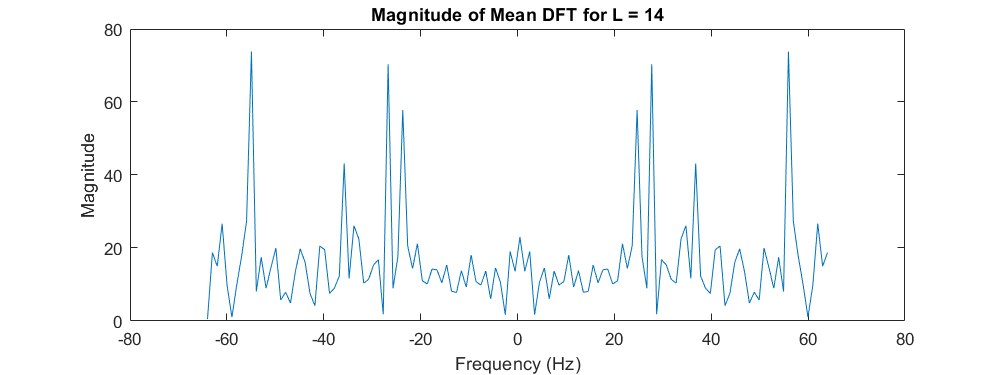

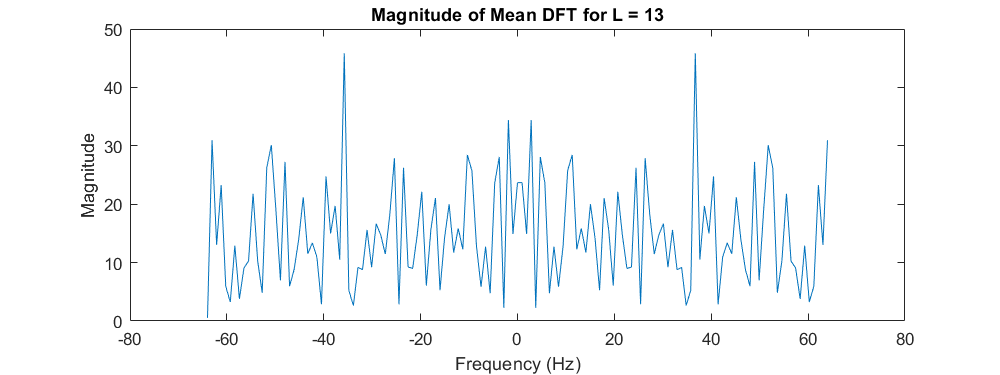

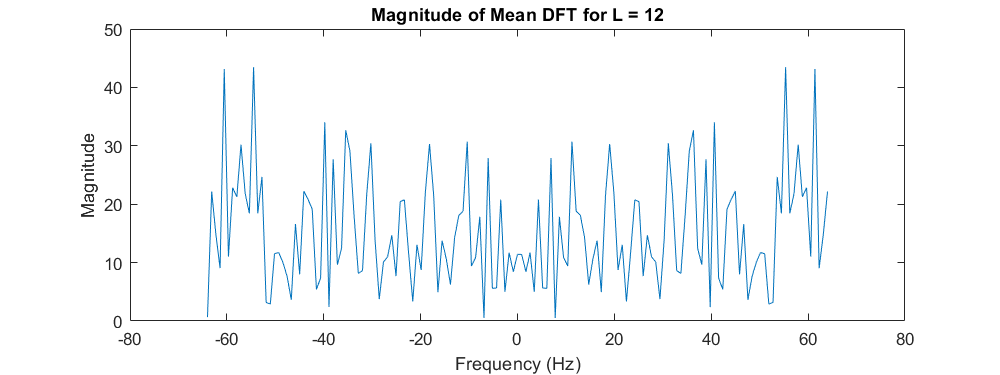

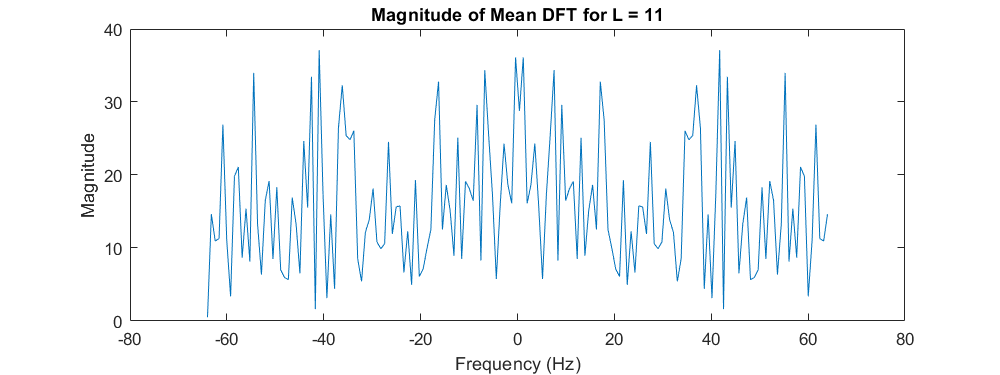

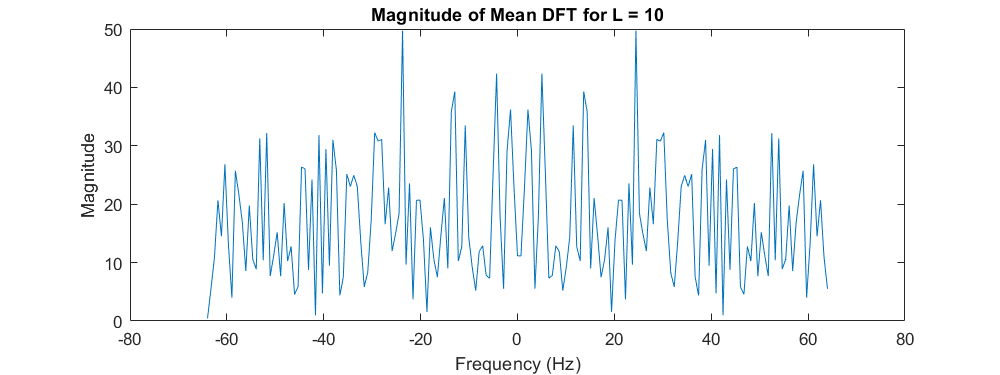

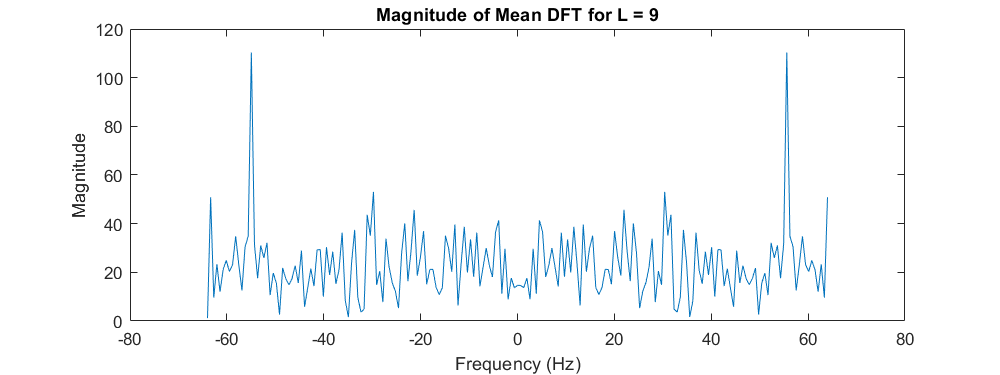

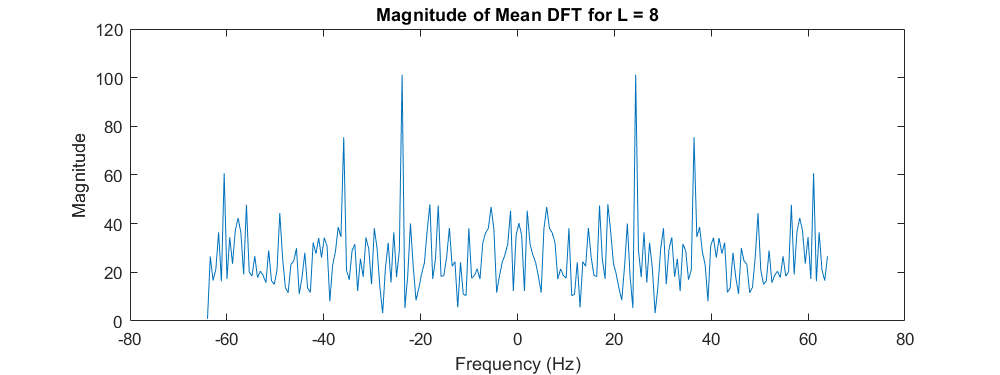

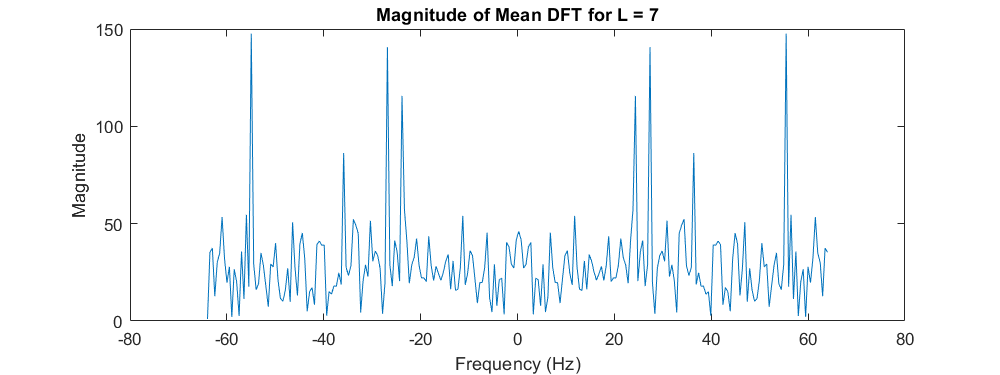

% Find the smallest value for L

% Define the parameters
N = 1792; % Total number of samples
for L = 14:-1:1 % Number of subsets
    K = floor(N/L);  % Number of samples in each subset

    % Initialize a cell array to store the subsets
    subsets = cell(1, L);
    
    % Partition the input signal into L subsets
    for i = 1:L
        start_idx = (i - 1) * K + 1;
        end_idx = i * K;
        subsets{i} = xn_test(start_idx:end_idx);
    end
    
    % Each subset is stored in the 'subsets' cell array, e.g., subsets{1} contains the first subset, subsets{2} contains the second subset, and so on.
    
    % Apply dft for each subset
    
    % Initialize a cell array to store the dft of subsets
    dft_subsets = cell(1, L);
    
    for i = 1:L
        dft_subsets{i} = fft(subsets{i},K);
    end
    
    
    % Calculate the arithmetic mean of the L sets of DFT sequences
    mean_DFT = zeros(1, K);  % Initialize an array to store the mean DFT
    
    for i = 1:L
        mean_DFT = mean_DFT + dft_subsets{i};
    end
    
    mean_DFT = mean_DFT / L;  % Divide by L to get the mean
    
    % Now, mean_DFT contains the arithmetic mean of the L sets of DFT sequences.
    % mean_DFT[k] represents the mean value at frequency bin k.
    
    
    
    % Create a frequency axis
    frequencies = linspace(-fs/2, fs/2, K);
    
    % Plot the magnitude of the mean DFT
    figure('Position', [100, 100, 800, 300]);
    plot(frequencies, abs(mean_DFT));
    title(['Magnitude of Mean DFT for L = ', num2str(L)]);
    xlabel('Frequency (Hz)');
    ylabel('Magnitude');

end

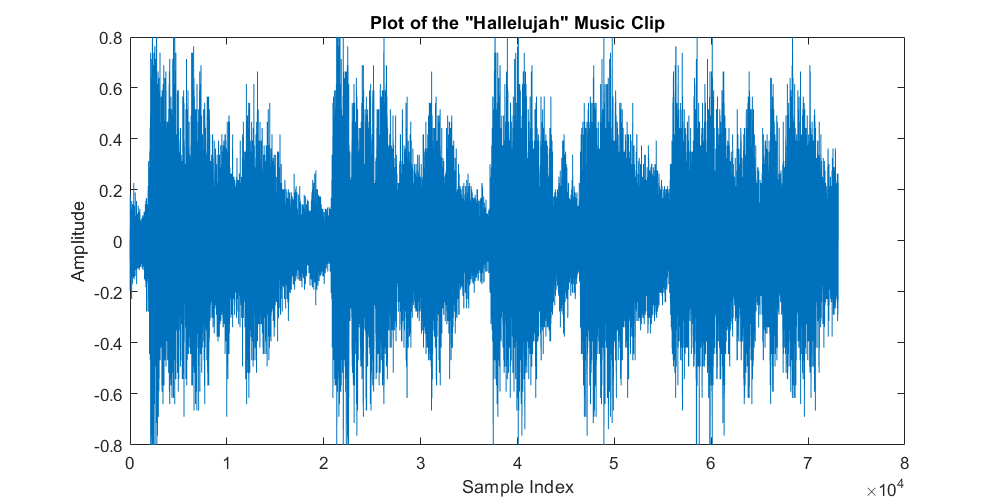

% Load the test signal%
load handel
% The signal is now avilable as y

% To plot the signal:
figure('Position', [100,100,800,400])
plot(y);
title('Plot of the "Hallelujah" Music Clip');
xlabel('Sample Index');
ylabel('Amplitude');

% Generate Signals
N = 20000;
x = y(1:N);
x2 = x(1:2:N);
x3 = x(1:3:N);
x4 = x(1:4:N);